# Show Productive Structure Demo

Use ShowProductiveStructure to show the productive structure of the plant 

#### Read Data Model

file='tgas_model.xml';
data=ReadDataModel(file);

#### Get the Productive Structure Tables

res=ShowProductiveStructure(data);
printResults(res);

Flows Table

  Id  Key  From     To       Type     
---------------------------------------
   1  NG   ENV_R1   COMB_F0  RESOURCE 
   2  B2   COMP_P0  COMB_P0  INTERNAL 
   3  B3   COMB_P0  GTRB_F0  INTERNAL 
   4  B4   GTRB_F0  HRSG_F0  INTERNAL 
   5  B5   HRSG_F0  STCK_F0  INTERNAL 
   6  WC   GTRB_P0  COMP_F0  INTERNAL 
   7  WN   GTRB_P0  ENV_O1   OUTPUT   
   8  QV   HRSG_P0  ENV_O2   OUTPUT   
   9  QG   STCK_P0  ENV_W1   WASTE    


Streams Table

  Id  Key      Definition  Type     
-------------------------------------
   1  COMB_F0  NG          FUEL     
   2  COMB_P0  B3-B2       PRODUCT  
   3  COMP_F0  WC          FUEL     
   4  COMP_P0  B2          PRODUCT  
   5  GTRB_F0  B3-B4       FUEL     
   6  GTRB_P0  WC+WN       PRODUCT  
   7  HRSG_F0  B4-B5       FUEL     
   8  HRSG_P0  QV          PRODUCT  
   9  STCK_F0  B5          FUEL     
  10  STCK_P0  QG          PRODUCT  
  11  ENV_R1   NG          RESOURCE 
  12  ENV_O1   WN          OUTPUT   
  13  ENV_O2   QV    

#### Show Flows Diagram

Use the cResultsInfo method flowsDiagram to obtain the flows diagram

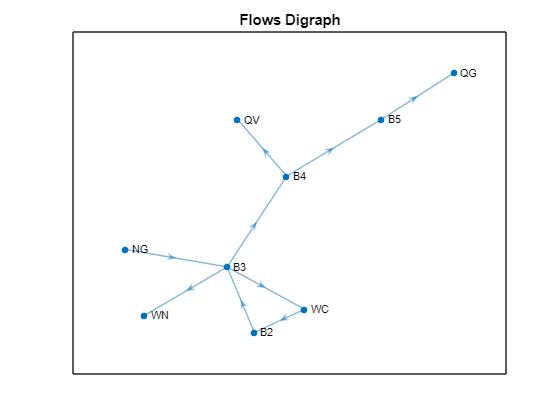

res.flowsDiagram(true);